A = [1,2,3;0,4,1;-1,5,-2]

A =      1     2     3
     0     4     1
    -1     5    -2


norm(A,1)

ans =     11


norm(A,inf)

ans =      8


norm(A,2)

ans =    6.724002372068454


norm(A,'fro')

ans =    7.810249675906654


sum(sum(abs(A).^2))^(1/2)

ans =    7.810249675906654


Sistemul 

Ax = b

A, b date de intrare, x de iesire

x = f(A,b) = $A^{-1} b$


$$f:\Re^{\textrm{nxn}} x\Re^{\textrm{nx1}} \to \Re^{\textrm{nx1}}$$



$${\textrm{cond}}_f \left(\left(A,b\right)\right)=||A|||*|A^{-1} ||$$


## Problema 1


$$\left\lbrack \begin{array}{cccc}
10 & 7 & 8 & 7\\
7 & 5 & 6 & 5\\
8 & 6 & 10 & 9\\
7 & 5 & 9 & 10
\end{array}\right\rbrack *x=\left\lbrack \begin{array}{c}
32\\
23\\
33\\
31
\end{array}\right\rbrack$$


A=[10, 7, 8, 7;7,5,6,5;8,6,10,9;7,5,9,10];
b=[32;23;33;31];
xe = A\b

xe =      1
     1
     1
     1


Perturbăm membrul drept $b_p =\left\lbrack \begin{array}{c}
32\ldotp 1\\
22\ldotp 9\\
33\ldotp 1\\
30\ldotp 9
\end{array}\right\rbrack$

bp = [32.1;22.9;33.1;30.9];
xp1=A\bp

xp1 =    9.199999999999680
 -12.599999999999463
   4.499999999999858
  -1.099999999999915


eri1 = norm(b-bp)/norm(b);
ero1=norm(xe-xp1)/norm(xe);
factor_aplificare = ero1/eri1

factor_aplificare =      2.460567236431338e+03



$$\textrm{Perturbam}\;\textrm{matricea}\;A_p =\left\lbrack \begin{array}{cccc}
10 & 7 & 8\ldotp 1 & 7\ldotp 2\\
7\ldotp 08 & 5\ldotp 04 & 6 & 5\\
8 & 5\ldotp 98 & 9\ldotp 89 & 9\\
6\ldotp 99 & 4\ldotp 99 & 9 & 9\ldotp 98
\end{array}\right\rbrack *x=\left\lbrack \begin{array}{c}
32\\
23\\
33\\
31
\end{array}\right\rbrack$$


Ap = [10, 7, 8.1, 7.2 ; 7.08,5.04,6,5; 8,5.98,9.98, 9;6.99,4.99,9,9.98];
xp2 = Ap\b

xp2 =   -5.792243651257218
  12.018809315278880
  -1.565554294241548
   2.565522373468965


eri2 = norm(A-Ap)/norm(A);
ero2=norm(xe-xp2)/norm(xe);
factor_aplificare = ero2/eri2

factor_aplificare =      8.963806327142571e+02


Raportul mare dintre eroarea relativa la iesire si eroarea relativa la intrare se aplica prin numarul de conditionare ${\textrm{cond}}_A =||A||*||A^{-1} ||$

cond(A)

ans =      2.984092701675700e+03


det(A)

ans =    1.000000000000049


inv(A)

ans =   25.000000000000576 -41.000000000000945  10.000000000000227  -6.000000000000136
 -41.000000000000945  68.000000000001535 -17.000000000000369  10.000000000000222
  10.000000000000227 -17.000000000000369   5.000000000000089  -3.000000000000053
  -6.000000000000136  10.000000000000222  -3.000000000000053   2.000000000000032


## Problema 2

Matricea Hilbert


$$H_{\textrm{ij}} =\frac{1}{i+j+1}$$


$H_4$ este

sym(hilb(4))

$$ans = \left(\begin{array}{cccc} 1 & \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4} & \frac{1}{5}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} & \frac{1}{6}\\ \frac{1}{4} & \frac{1}{5} & \frac{1}{6} & \frac{1}{7} \end{array}\right)$$

sym(invhilb(4))

$$ans = \left(\begin{array}{cccc} 16 & -120 & 240 & -140\\ -120 & 1200 & -2700 & 1680\\ 240 & -2700 & 6480 & -4200\\ -140 & 1680 & -4200 & 2800 \end{array}\right)$$


$${\textrm{cond}}_2 \left(H_n \right)=\lambda_{\max } \left(H_n \right)\lambda_{\max } \left(H_n^{-1} \right)$$



$$O\;\textrm{estimare}\;\textrm{teoretica}\;\textrm{pentru}\;n\;\textrm{mare}\;\textrm{este}:{\textrm{cond}}_2 \left(H_n \right)=\frac{{\left(1+\sqrt{2}\right)}^{4n+4} }{2^{\frac{15}{4}} \sqrt{\pi n}}$$


for n=10:10:100
    c = max(eig(hilb(n)))*max(eig(invhilb(n)));
    th = (sqrt(2)+1)^(4*n+4)/(2^(15/4)*sqrt(pi*n));
    fprintf("%3d %11.4e %11.4e\n",n,c,th)
end

 10  1.6026e+13  9.2192e+14
 20  2.4522e+28  1.3342e+30
 30  4.2278e+43  2.2294e+45
 40  7.6529e+58  3.9513e+60
 50  1.4229e+74  7.2330e+75
 60  2.6913e+89  1.3513e+91
 70 5.1508e+104 2.5604e+106
 80 9.9444e+119 4.9016e+121
 90 1.9328e+135 9.4578e+136
100 3.7765e+150 1.8363e+152


H=hilb(10);
b=H*ones(10,1);
format long
x=H\b

x =    0.999999999095413
   1.000000077638004
   0.999998354294758
   1.000014906295676
   0.999929106136442
   1.000194425970870
   0.999681635015205
   1.000307148615796
   0.999838981464458
   1.000035366078449


warning off
for n=[10,20,40,80]
    t = linspace(-1,1,n);
    V=vander(t);
    et=1/pi*exp(-pi/4)*exp(n*(pi/4+1/2*log(2)));
    x=[n,norm(V,inf)*norm(inv(V),inf),condest(V),et];
    fprintf("%3d %e %e    %e\n",x)
end

 10 2.056171e+04 1.362524e+04    1.196319e+04
 20 1.751063e+09 1.053490e+09    9.861382e+08
 40 1.208386e+19 6.926936e+18    6.700689e+18
 80 1.493675e+38 8.637996e+37    3.093734e+38


warning on

warning off
for n=10:15
    t=1./(1:n);
    V=vander(t);
    x=[n, norm(V,inf)*norm(inv(V),inf), condest(V), n^(n+1)];
    fprintf("%3d %e %e    %e\n", x)
end

 10 5.792417e+11 5.905580e+11    1.000000e+11
 11 2.382382e+13 2.278265e+13    3.138428e+12
 12 1.060780e+15 9.692982e+14    1.069932e+14
 13 5.087470e+16 4.732000e+16    3.937376e+15
 14 2.615990e+18 2.419006e+18    1.555681e+17
 15 1.436205e+20 1.294189e+20    6.568408e+18


warning on


$$P=a_0 x^n +a_1 x^{n-1} +\ldotp \ldotp \ldotp +a_n$$


P=? a.i. $P\left(x_i \right)=b_i$

<= Vandermonde

## Problema 4

n=20;
v=1:20;
P=poly(v);
roots(P)

ans =   19.999874055724192
  19.001295393676987
  17.993671562737585
  17.018541647321989
  15.959717574548915
  15.059326234074415
  13.930186454760916
  13.062663652011070
  11.958873995343460
  11.022464271003383


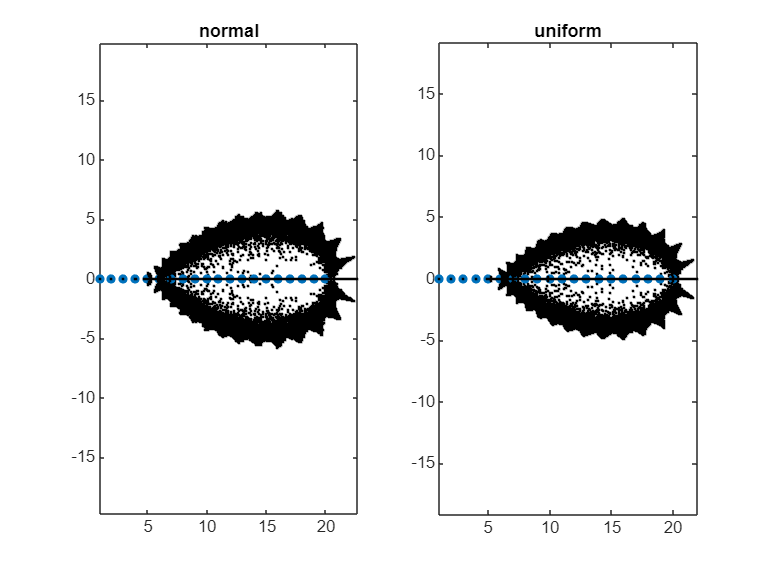

function nc=condpol(p,xi)
    if nargin < 2
        xi = roots(p);
    end
    n=length(p)-1;
    dp=(n:-1:1).*p(1:end-1);
    nc=1./(abs(xi.*polyval(dp,xi))).*(polyval(abs(p(2:end)),abs(xi)));
end

function wilkinson(n)
    p=poly(1:n);
    h=plot(1:n,zeros(1,n),'.');
    set(h,'Markersize',15);
    hold on
    for k=1:1000
        r = randn(1,n+1);
        pr=p.*(1+1e-10*r);
        z=roots(pr);
        h2=plot(z,'k.');
        set(h2,'Markersize',4)
    end
    axis equal
end

function wilkinsonu(n)
    p=poly(1:n);
    h=plot(1:n,zeros(1,n),'.');
    set(h,'Markersize',15);
    hold on
    for k=1:1000
        r = (1e-10)*rand(1,n+1);
        pr=p + r.*p;
        z=roots(pr);
        h2=plot(z,'k.');
        set(h2,'Markersize',4)
    end
    axis equal
end

subplot(1,2,1)
wilkinson(20)
title('normal')
subplot(1,2,2)
wilkinsonu(20)
title('uniform')

## Problema 5

function E=recdir(n)
    E=1/exp(1);
    for k=2:n
        E = 1-k*E;
    end
end

for n=2:25
    E = recdir(n);
    fprintf("E(%2d)=%+6.4e\n",n,E)
end

E( 2)=+2.6424e-01
E( 3)=+2.0728e-01
E( 4)=+1.7089e-01
E( 5)=+1.4553e-01
E( 6)=+1.2680e-01
E( 7)=+1.1238e-01
E( 8)=+1.0093e-01
E( 9)=+9.1612e-02
E(10)=+8.3877e-02
E(11)=+7.7352e-02
E(12)=+7.1773e-02
E(13)=+6.6948e-02
E(14)=+6.2731e-02
E(15)=+5.9034e-02
E(16)=+5.5459e-02
E(17)=+5.7192e-02
E(18)=-2.9454e-02
E(19)=+1.5596e+00
E(20)=-3.0192e+01
E(21)=+6.3504e+02
E(22)=-1.3970e+04
E(23)=+3.2131e+05
E(24)=-7.7114e+06
E(25)=+1.9279e+08



$$\begin{array}{l}
E_n =1-nE_{n-1} =1-n\left(1-\left(n-1\right)E_{n-2} \right)=1-n+n\left(n-1\right)E_{n-2} =\ldotp \ldotp \ldotp =P\left(n\right)+{\left(-1\right)}^n n!E_1 \\
\textrm{cond}\left(f\right)\left(E_1 \right)=\frac{|E_1 ||\frac{\partial f}{\partial E_1 }|}{|E_n |}>\frac{E_1 }{E_1 }n!\;=n!\\
\\
\textrm{Se}\;\textrm{aplica}\;\textrm{in}\;\textrm{ordinea}\;\textrm{inversa}\;E_{n-1} =\frac{1-E_n }{n}\\
E_n =\frac{1-E_{n+1} }{n+1}=\frac{1-\frac{1-E_{n+2} }{n+2}}{n+1}=\frac{1}{n+2}+\frac{E_{n+2} }{\left(n+1\right)\left(n+2\right)}=\frac{n+2}{\left(n+3\right)\left(n+1\right)}-\frac{E_{n+3} }{\left(n+1\right)\left(n+2\right)\left(n+3\right)}=Q\left(n\right)+{\left(-1\right)}^k \frac{E_{n+k} }{\left(n+1\right)\ldotp \ldotp \ldotp \left(n+k\right)}\\
\textrm{cond}\left(g\right)\left(E_{n+k} \right)=\frac{\left|E_{n+k} \frac{\partial g\left(E_{n+1} \right)}{\partial E_{n+k} }\right|}{\left|E_n \right|}=\frac{E_{n+k} \frac{1}{\left(n+1\right)\ldotp \ldotp \ldotp \left(n+k\right)}}{E_n }<\frac{E_{n+k} \frac{1}{\left(n+1\right)\ldotp \ldotp \ldotp \left(n+k\right)}}{E_{n+k} }=\frac{1}{\left(n+1\right)\ldotp \ldotp \ldotp \left(n+k\right)}\\
\textrm{cu}\;\textrm{cat}\;k\;e\;\textrm{mai}\;\textrm{mare},\textrm{cu}\;\textrm{atat}\;\textrm{factorul}\;\textrm{este}\;\textrm{mai}\;\textrm{mic}
\end{array}$$


function E=recinv(n,k)
    E =0;
    for j =n+k:-1:n+1
        E=(1-E)/j;
    end
end

for k = 10:18
    E=recinv(1,k);
    err=abs(E-exp(-1))/exp(-1);
    fprintf("k=%2d, err=%e\n",k, err);
end

k=10, err=5.267586e-09
k=11, err=4.073053e-10
k=12, err=2.922473e-11
k=13, err=1.955900e-12
k=14, err=1.228285e-13
k=15, err=7.242958e-15
k=16, err=4.526849e-16
k=17, err=0.000000e+00
k=18, err=0.000000e+00


## Problema facultativa

Problema 1

syms x;
n = 5; 
expr = 1;

for k = 1:n
    expr = expr * (x - k)^2;
end

poly_coeffs = expand(expr);
p = fliplr(coeffs(poly_coeffs, x)); 
p = conv(poly(1:n), poly(1:n))

p =            1         -30         395       -3000       14523      -46710      100805     -143700      129076      -65760       14400


roots(p)

ans =   5.000000000545187 + 0.000019154353446i
  5.000000000545187 - 0.000019154353446i
  4.000000000125278 + 0.000039249468894i
  4.000000000125278 - 0.000039249468894i
  2.999999999382530 + 0.000024650082796i
  2.999999999382530 - 0.000024650082796i
  1.999999999947220 + 0.000004728559499i
  1.999999999947220 - 0.000004728559499i
  0.999999999999783 + 0.000000282835717i
  0.999999999999783 - 0.000000282835717i


condpol(p)

ans = 1.0e+10 *

   0.819994152416343
   0.819994152416343
   2.013171457325261
   2.013171457325261
   1.905814711570648
   1.905814711570648
   0.932480364916369
   0.932480364916369
   0.159102653708067
   0.159102653708067
